clear; clc; close all;

% =========================
% ALL FOOD ITEMS
% [mass; calories; protein; fat; carbs]
% mass entry is per gram of food
% =========================

% Food A: Chia seeds
FoodA = [1; 4.86; 0.17; 0.31; 0.42];

% Food B: Spirulina
FoodB = [1; 2.9; 0.57; 0.08; 0.24];

% Food C: Chlorella
FoodC = [1; 4.0; 0.58; 0.12; 0.23];

% Food D: Oyster mushrooms
FoodD = [1; 0.33; 0.033; 0.004; 0.06];

% Food E: Lion's mane mushrooms
FoodE = [1; 0.35; 0.02; 0.005; 0.07];

% Food F: Crickets (dried)
FoodF = [1; 4.8; 0.65; 0.20; 0.10];

% Food G: Mealworms (dried)
FoodG = [1; 5.0; 0.50; 0.30; 0.10];

% =========================
% DIET 1 (7-DAY LOOP)
% Each day is [mass; calories; protein; fat; carbs] for each food eaten
% =========================

Day1_1 = [FoodA*50, FoodB*30, FoodC*15, FoodD*250, FoodE*200, FoodF*40, FoodG*80];
Day2_1 = [FoodA*20, FoodB*35, FoodC*10, FoodD*350,               FoodF*40, FoodG*80];
Day3_1 = [FoodA*40, FoodB*35, FoodC*10, FoodD*350,               FoodF*70];
Day4_1 = [FoodA*20, FoodB*50, FoodC*20,              FoodE*100,  FoodF*50];
Day5_1 = [FoodA*20, FoodB*45, FoodC*15, FoodD*300,                            FoodG*80];
Day6_1 = [FoodA*15, FoodB*25,              FoodD*150, FoodE*200, FoodF*70, FoodG*60];
Day7_1 = [FoodA*35, FoodB*40,              FoodD*150, FoodE*200,             FoodG*90];

Days = {Day1_1, Day2_1, Day3_1, Day4_1, Day5_1, Day6_1, Day7_1};

% =========================
% INITIAL TOTAL MASS AVAILABLE
% =========================

total_mass = 10000;   % g
N = 30;            % number of simulated days

% =========================
% STORAGE
% =========================

remaining_mass = zeros(1,N);
mass_used      = zeros(1,N);
calories       = zeros(1,N);
protein        = zeros(1,N);
fat            = zeros(1,N);
carbs          = zeros(1,N);

% =========================
% RUN SIMULATION
% =========================

for t = 1:N
    
    day_idx = mod(t-1,7) + 1;
    current_day = Days{day_idx};
    
    daily_total = sum(current_day, 2);   % [mass; calories; protein; fat; carbs]
    daily_mass_used = daily_total(1);
    
    mass_used(t) = daily_mass_used;
    calories(t)  = daily_total(2);
    protein(t)   = daily_total(3);
    fat(t)       = daily_total(4);
    carbs(t)     = daily_total(5);
    
    if t == 1
        remaining_mass(t) = total_mass - daily_mass_used;
    else
        remaining_mass(t) = remaining_mass(t-1) - daily_mass_used;
    end
    
    if remaining_mass(t) <= 0
        remaining_mass(t:end) = 0;
        mass_used(t+1:end) = 0;
        calories(t+1:end) = 0;
        protein(t+1:end) = 0;
        fat(t+1:end) = 0;
        carbs(t+1:end) = 0;
        break;
    end

end

time = 1:N;

% =========================
% OPTIONAL: print first few daily masses
% =========================

disp('First 10 daily mass usages (g):')

First 10 daily mass usages (g):


disp(mass_used(1:10))

   665   535   505   240   460   520   515   665   535   505



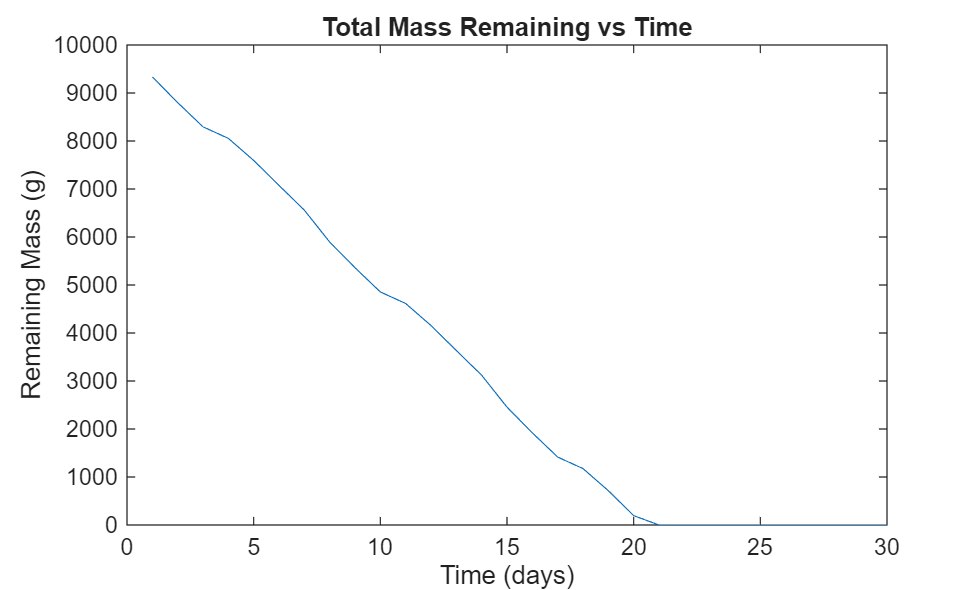


% =========================
% PLOTS
% =========================

figure;
plot(time, remaining_mass);
xlabel('Time (days)');
ylabel('Remaining Mass (g)');
title('Total Mass Remaining vs Time');

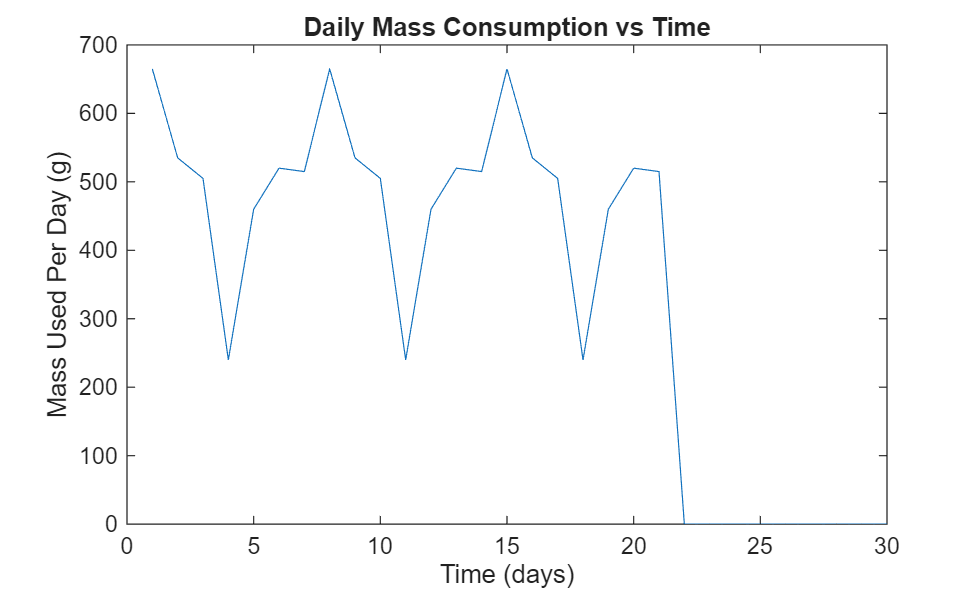


figure;
plot(time, mass_used);
xlabel('Time (days)');
ylabel('Mass Used Per Day (g)');
title('Daily Mass Consumption vs Time');

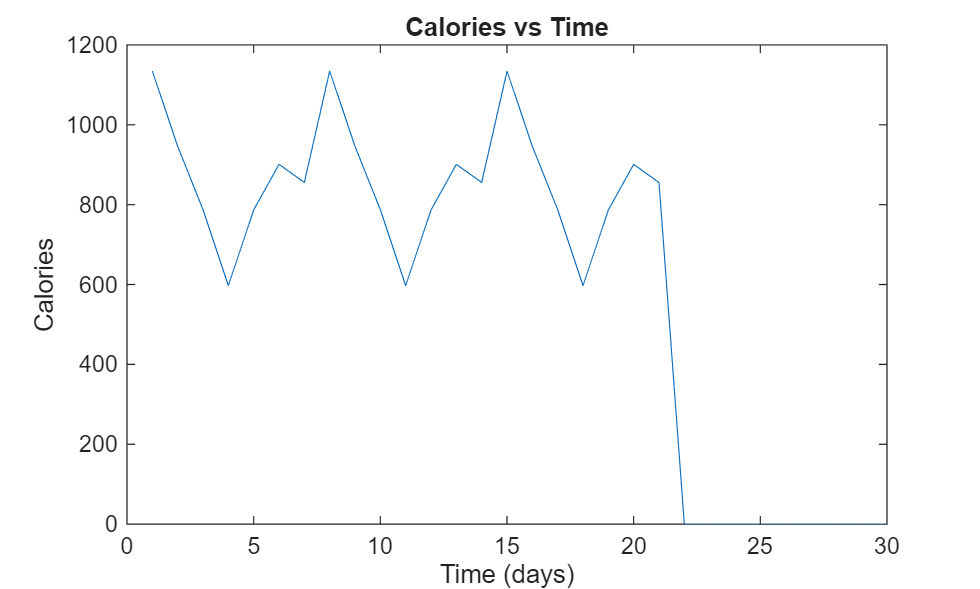


figure;
plot(time, calories);
xlabel('Time (days)');
ylabel('Calories');
title('Calories vs Time');

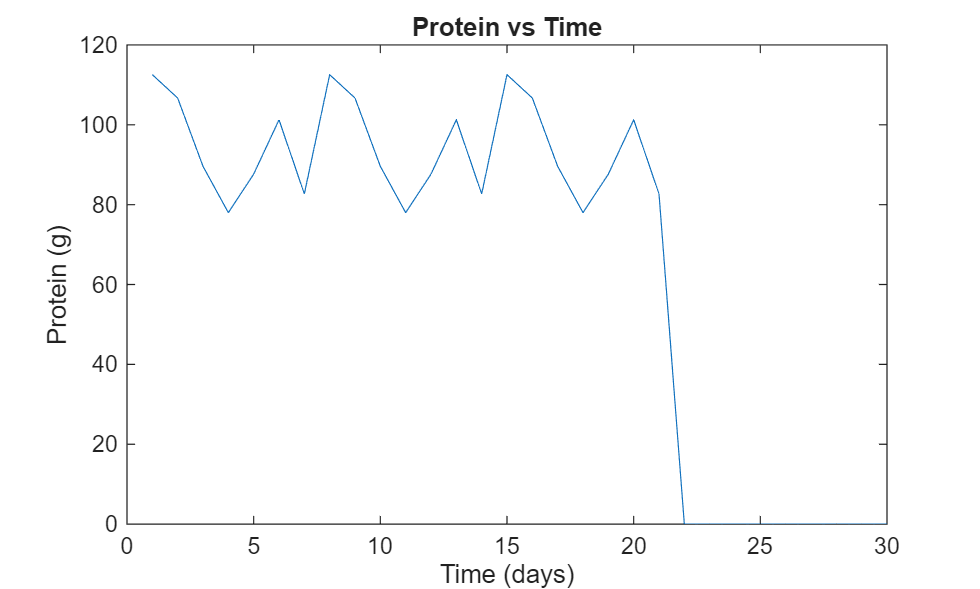


figure;
plot(time, protein);
xlabel('Time (days)');
ylabel('Protein (g)');
title('Protein vs Time');

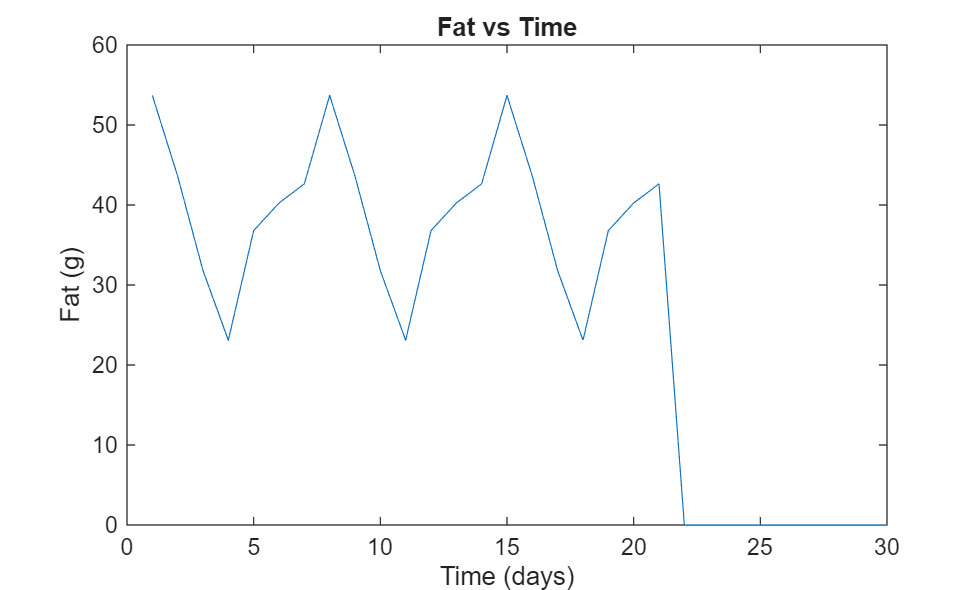


figure;
plot(time, fat);
xlabel('Time (days)');
ylabel('Fat (g)');
title('Fat vs Time');

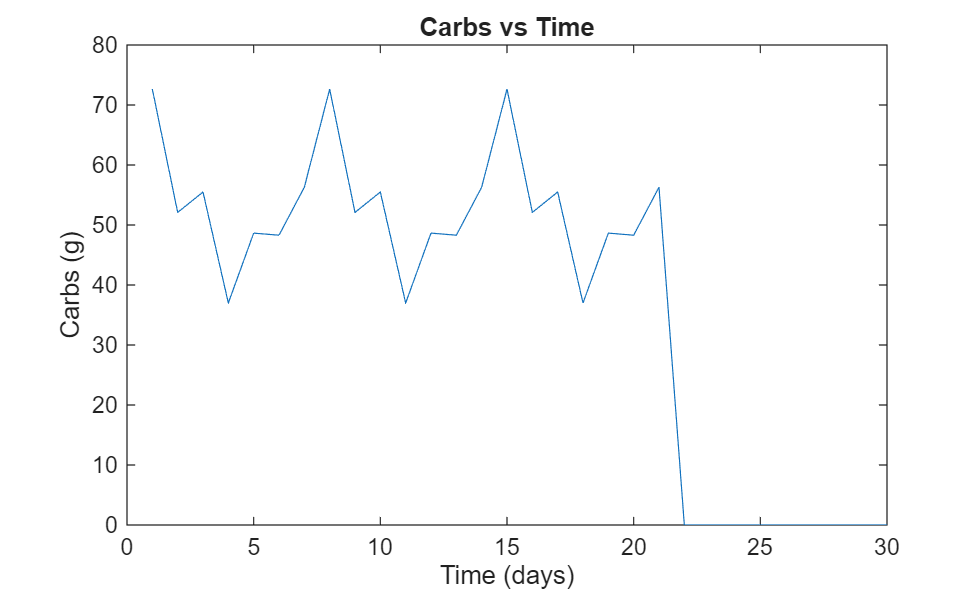

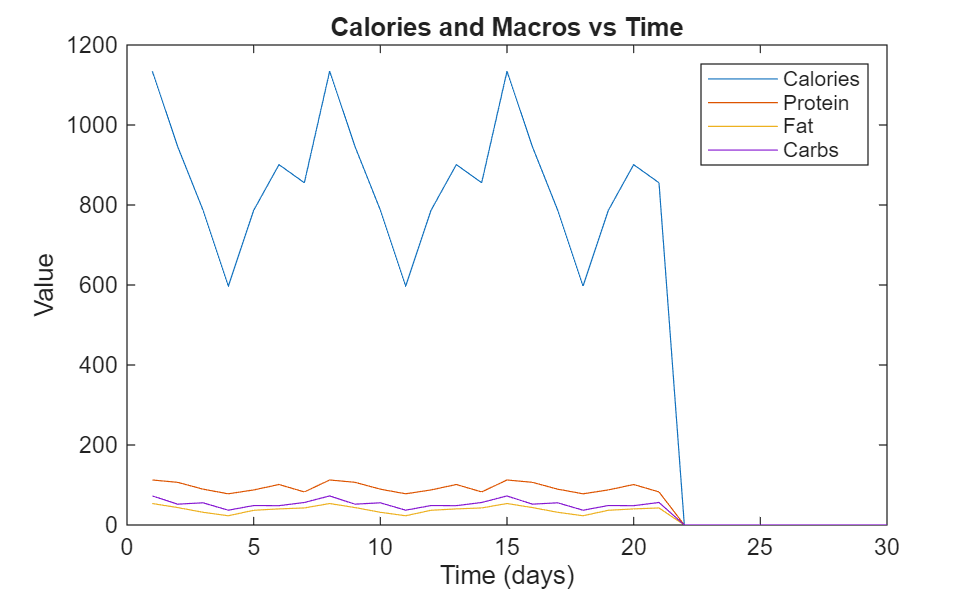


figure;
plot(time, carbs);
xlabel('Time (days)');
ylabel('Carbs (g)');
title('Carbs vs Time');